# Getting Started with MRMCaov

## Description

MRMCaov contains statistical tools for estimating and comparing the performances of diagnostic tests in multi-reader multi-case studies where true case statuses (or ground truths) are known and one or more readers provide test ratings for multiple cases.

## Features

- Statistical comparisons of diagnostic tests with respect to reader performance metrics

- Comparisons based on the ANOVA model of Obuchowski-Rockette and the unified framework of Hillis

- Reader performance metrics for area under receiver operating characteristic curves (ROC AUCs), partial AUCs, expected utility of ROC curves, likelihood ratio of positive or negative tests, sensitivity, specificity, and user-defined metrics

- Support for factorial, nested, and partially paired study designs

- Inference for random or fixed readers and cases

- DeLong, jackknife, and unbiased covariance estimation

## Examples

In the following example, an MRMC analysis of the supplied VanDyke dataset is performed to compare area under the ROC curve (ROC AUC) in a study where multiple readers (reader) rated the disease severity of multiple cases (case) based on two separate diagnostic tests (treatment).  MRMCaov toolbox fuinctions are used to display their ROC curves, estimates, and statistical comparisons. 

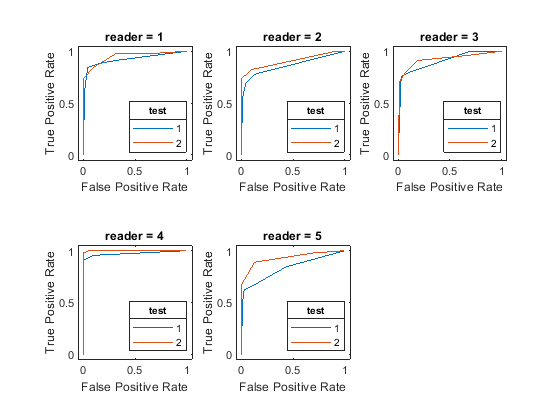

% Load the study data
load VanDyke

% Designate ROC AUC as the reader performance metric
y = ROCAUCVariate(VanDyke.truth, VanDyke.rating);

% Perform an MRMC analysis
fit = mrmc(y, VanDyke.treatment, VanDyke.reader, VanDyke.case, 'cov', 'unbiased');

% Plot the ROC curves
plot(fit)

% Display fitted values from the analysis
disp(fit)

ROCAUCVariate ANOVA data:

    reader    test       y        N 
    ______    ____    _______    ___

      1        1      0.91965    114
      1        2      0.94783    114
      2        1      0.85878    114
      2        2      0.90531    114
      3        1      0.90386    114
      3        2      0.92174    114
      4        1      0.97311    114
      4        2      0.99936    114
      5        1      0.82979    114
      5        2      0.92995    114

ANOVA Table:

        Source         d.f.     Sum Sq.        Mean Sq.   
    _______________    ____    _________    ______________

    {'reader'     }     4       0.015345    {[    0.0038]}
    {'test'       }     1      0.0047962    {[    0.0048]}
    

% Summarize statistical results the analysis.
summary(fit)

ans = Multi-Reader Multi-Case Analysis of Variance
Experimental design: factorial
Factor types: random readers and random cases
Response: ROCAUCVariate
Covariance method: unbiased
Confidence interval level: 95%

Obuchowski-Rockette variance component and covariance estimates:

                    Estimate     Correlation
                   __________    ___________

    reader          0.0015365          NaN  
    reader*test    0.00020776          NaN  
    Error          0.00078839          NaN  
    Cov1           0.00034167      0.43338  
    Cov2           0.00033906      0.43007  
    Cov3           0.00023561      0.29885  

ANOVA global statistical test of equal tests:

      MS(T)       MS(T:R)         Cov2          Cov3       Denomina